## Tutorial 6 - Problem 3a-d, PI-controller

clc; clear all; close all;

% Data for problem 3
zeta = 0.85;
lambda = 10;

% Data from problem 2 (I guess it is supposed to be the DC motor described
% in problem 2?)
J_m = 0.004; % kg*m^2
J_eff = J_m;

U_a_max = 12; % V
R_a = 1.1; % Ohm
K_m = 0.2; % Nm/A
% L is neglected

K_sys = 0.9; % Steady state speed

% a)
K_p = (K_m)/(2*lambda*zeta-1)

K_p =                     0.0125



% b)
tau_i = 1/lambda^2 * (R_a*J_eff)/(K_m*K_p)

tau_i =                     0.0176



% c)
omega_sys = sqrt((K_m*K_p)/(R_a*J_eff*tau_i))

omega_sys =           5.68181818181818


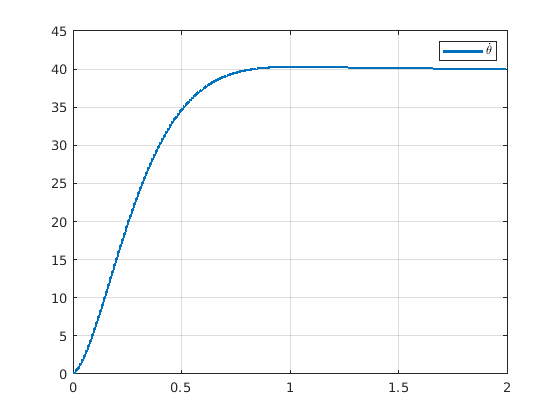


% d)
thetaDot_ref = 40; % rad/s
simTime = 2; % s
theta = 0; % rad
thetaDot = 0; % rad/s
thetaDot_err_int = 0;

t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    % Calculations
    thetaDot_err = thetaDot_ref - thetaDot;
    
    U_a = K_p * thetaDot_err + K_p/tau_i * thetaDot_err_int;
    if(U_a >= U_a_max)
        U_a = U_a_max;
    end

    i_a = (U_a-K_m*thetaDot)/R_a; % Equation 5.19 from notes

    M_m = K_m*i_a; % Equation 5.16 from notes

    thetaDotDot = M_m/J_eff; % Equation 5.15 from notes
    % Logging
    time_plot(idx) = t;
    thetaDot_plot(idx) = thetaDot;

    % Time Integrate
    thetaDot = thetaDot + thetaDotDot * dt;
    thetaDot_err_int = thetaDot_err_int + thetaDot_err * dt;
    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(time_plot, thetaDot_plot, 'LineWidth', 2)
legend("$\dot{\theta}$", 'Interpreter','latex')
grid

## Tutorial 6 - Problem 3e, PI-controller with inductance

clc; clear all;

% Data for problem 3
zeta = 0.85;
lambda = 10;

% Data from problem 2 (I guess it is supposed to be the DC motor described
% in problem 2?)
J_m = 0.004; % kg*m^2
J_eff = J_m;

U_a_max = 12; % V
R_a = 1.1; % Ohm
K_m = 0.2; % Nm/A
L_a = 0.015; % H
i_a = 0;

K_sys = 0.9; % Steady state speed

% a)
K_p = (K_m)/(2*lambda*zeta-1)

K_p =                     0.0125



% b)
tau_i = 1/lambda^2 * (R_a*J_eff)/(K_m*K_p)

tau_i =                     0.0176



% c)
omega_sys = sqrt((K_m*K_p)/(R_a*J_eff*tau_i))

omega_sys =           5.68181818181818


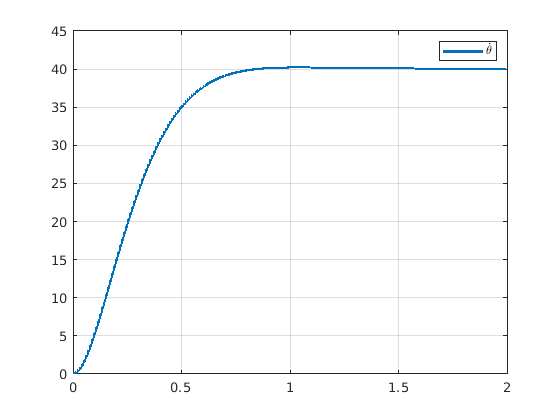


% d)
thetaDot_ref = 40; % rad/s
simTime = 2; % s
theta = 0; % rad
thetaDot = 0; % rad/s
thetaDot_err_int = 0;

t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    % Calculations
    thetaDot_err = thetaDot_ref - thetaDot;

    U_a = K_p * thetaDot_err + K_p/tau_i * thetaDot_err_int;
    if(U_a >= U_a_max)
        U_a = U_a_max;
    end

    %i_a = (U_a-K_m*thetaDot)/R_a; % Equation 5.19 from notes

    i_a_dot = 1/L_a * (U_a - R_a*i_a - K_m*thetaDot);

    M_m = K_m*i_a; % Equation 5.16 from notes

    thetaDotDot = M_m/J_eff; % Equation 5.15 from notes
    % Logging
    time_plot(idx) = t;
    thetaDot_plot(idx) = thetaDot;

    % Time Integrate
    thetaDot = thetaDot + thetaDotDot * dt;
    thetaDot_err_int = thetaDot_err_int + thetaDot_err * dt;
    i_a = i_a + i_a_dot * dt;
    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(time_plot, thetaDot_plot, 'LineWidth', 2)
legend("$\dot{\theta}$", 'Interpreter','latex')
grid